% do group analysis in group run vs stat script

%% TRACES - stationary & run

yLimit = [-0.15 0.05];

durat = 1;

cont = 7;

visArea = 1; % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

figure
suptitle('stat')
%formatSpec = 'vis area: %1.f (STAT)';
%titleText = sprintf(formatSpec,visArea);
% titleText = '100ms, STAT'
% suptitle(titleText)


% NEED this for UNIQUE CONS for C loop:

% EXTRACT VARS from GROUP CELL ARRAYS
clear n
n = 1

n = 1

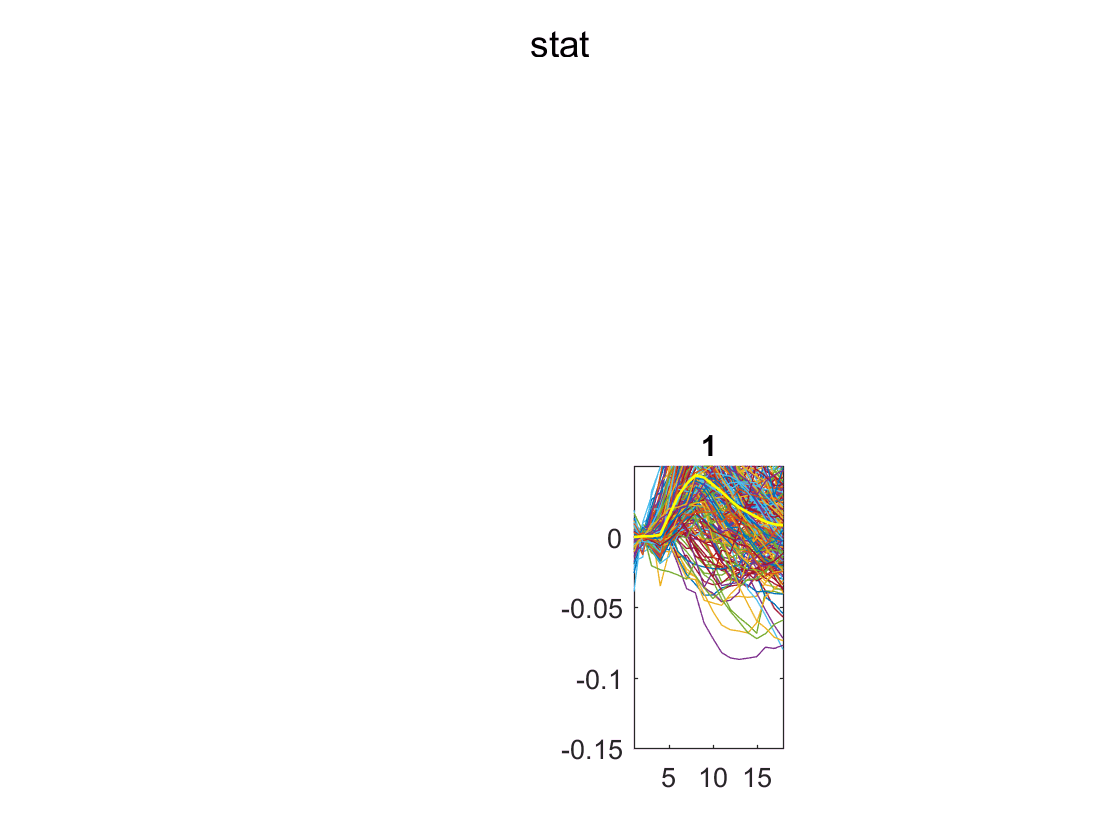

numIdxCthDthSTATtrials = 67

numIdxCthDthSTATtrials = 100

numIdxCthDthSTATtrials = 89

n = 1

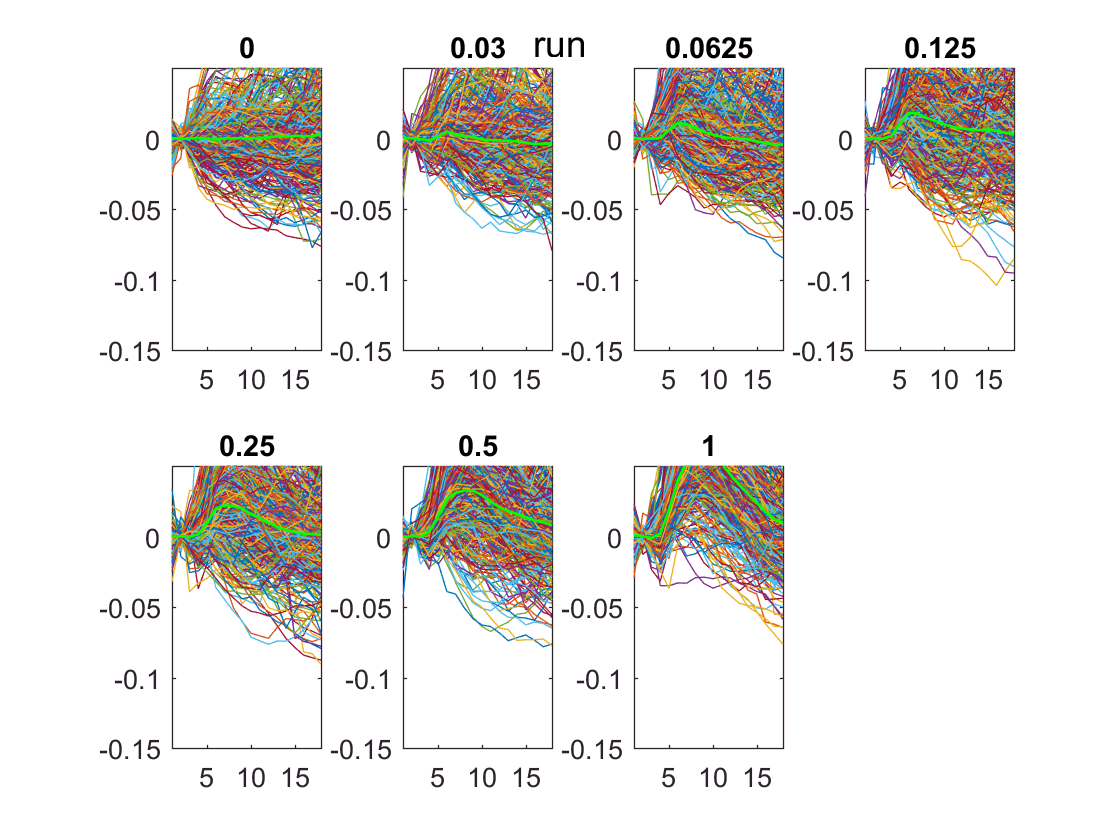

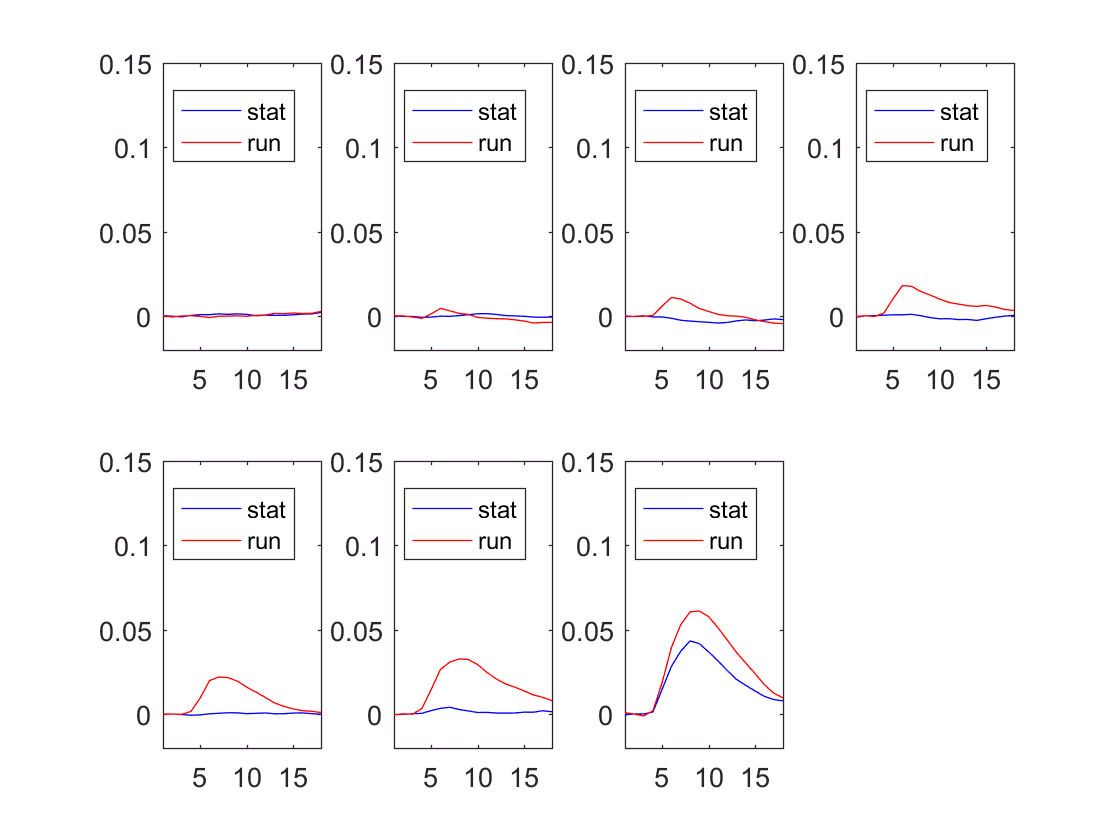

nthStimDetailsStruct = groupStimDetails{n};
nthTrialCond = groupTrialCond{1,n};
nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n};

% CONTRAST calc's
clear con
clear conOrderedByTrial  
clear conOrderedByTrialMeetCriteria 
clear uniqueContrasts
clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end
conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later

%  DURATION Calc's
clear dur
clear durOrderedByTrial  
clear durOrderedByTrialMeetCriteria 
clear uniqueDurations
% extract duration field from stimDetails
clear durs
for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end
durOrderedByTrial = dur(nthTrialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueDurations = unique(dur);

% CON & DUR TOGETHER
clear conAndDur 
clear conAndDurOrderedByTrial 
clear conAndDurOrderedByTrialMeetCriteria
conAndDur = [con; dur];
conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);



clear i
for i = visArea
    
    for d = durat
        
        loopCounter = 1;
        
        %for c = 1:length(uniqueContrasts)
        for c = cont
            
            clear n 
            for n = 1:nGroup % for each session/mouse
                
                % EXTRACT VARS from GROUP CELL ARRAYS
                nthStimDetailsStruct = groupStimDetails{n};
                nthTrialCond = groupTrialCond{1,n};
                nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n}; 
                
               
                % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
        
                % CONTRAST calc's
                clear con
                clear conOrderedByTrial  
                clear conOrderedByTrialMeetCriteria 
                clear uniqueContrasts
                clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
                for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
                    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
                end
                conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
                conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueContrasts = unique(con); % for looping over contrast values later
                
                %  DURATION Calc's
                clear dur
                clear durOrderedByTrial  
                clear durOrderedByTrialMeetCriteria 
                clear uniqueDurations
                % extract duration field from stimDetails
                clear durs
                for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
                    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
                end
                durOrderedByTrial = dur(nthTrialCond); 
                durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueDurations = unique(dur);
        
                % CON & DUR TOGETHER
                clear conAndDur 
                clear conAndDurOrderedByTrial 
                clear conAndDurOrderedByTrialMeetCriteria
                conAndDur = [con; dur];
                conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
                conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                
                % in preparation for making pixel wise figures of fluroescene at different stim conditions,
                % make figure legends
                [reigons,cons4Legend,cons4axes,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
                % durs4Legend = {'16 ms','33 ms', '66 ms', '133 ms', '266 ms'}
                durs4Legend = {'100 ms'};
        
                % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
                nthPTSdfof = groupPTSdfof{1,n};
                nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
                nthBaselineIdx = groupBaselineIdx{1,n};
                
                % EXTRACT RUN vs STAT TRIAL INDICIES
                nthIdxRunTrials = groupIdxRunTrials{1,n};
                nthIdxStatTrials = groupIdxStatTrials{1,n}; 
        
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,nthIdxStatTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)

                % part directly from old script
                
                clear recomboOnePtAllFramesAllTrialMinusMeanBase
                clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase

                % collect all cth dth trials over all frames for the ith point
                clear onePtAllFramesAndTrials % new var each point
                onePtAllFramesAndTrials = squeeze(nthPTSdfof(i,:,idxCthDthSTATtrials)); 
                onePtAllFramesAndTrials = onePtAllFramesAndTrials';

                % for every trace, subtract the baseline value at that point from each frame value
                clear tr % for each trial in onePtAllFramesAndTrial
                for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames

                    % getting TRIAL VECTOR
                    clear onePtAllFramesOneTrial % make new var for each trial
                    % index into each trace/vector & save as variable
                    onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);

                    % getting MEAN BASEline VALUE for each TRIAL
                    clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                    % collect 4 baseline frames for tr-th ith trial
                    allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,nthBaselineIdx);

                    clear mean4baseFramesOnePtOneTrial
                    % get mean value of baseline values for ith point
                    mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                    mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);

                    % BASEline CORRECTion of TRIAL VECTOR
                    % new baseline-corrected trace for each trial
                    onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;

                    % collect CORRECTed TRIAL VECTORS in matrix
                    % (only clear this outside the loop for each point)
                    recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;

                    % PLOT
                    clear x_axis
                    x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames

                    % plot one baseline corrected trace at a time
                    subplot(2,4,c)
                    plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                    title(uniqueContrasts(c))
                    
                    ylim(yLimit)
                    xlim([1 length(x_axis)])

                    hold on % hold for next trial
                
                end % end tr loop
      
                hold on % hold for plotting mean over subplot
                
            end % end n loop - now have all trials for all sesstions at cth contrast plotted
        
            % get mean baselined trace across all trials
            statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
            allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
            
            subplot(2,4,c)
            plot(x_axis,statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase,'color','y','linewidth',1)
            title(uniqueContrasts(c))

            ylim(yLimit)
            xlim([1 length(x_axis)])

            %ax = gca;
            %x.XTick = [1:1:length(x_axis)];

            loopCounter = loopCounter + 1;
        
            % go to next contrast after plotting mean trace
            
        end % end c loop
        
    end % end d loop
    
    % save for each point
    allPtsAllConsSTATMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(:,:,i) = allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
       
end % end i loop




% TRACES - running

%yLimit = [-0.15 0.25];

%durat = 5;

%visArea = 1; % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

figure
suptitle('run')
%formatSpec = 'vis area: %1.f (RUN)';
%titleText = sprintf(formatSpec,visArea);
% titleText = '100 ms, RUN'
% suptitle(titleText)


% NEED this for UNIQUE CONS for C loop:

% EXTRACT VARS from GROUP CELL ARRAYS
clear n
n = 1
nthStimDetailsStruct = groupStimDetails{n};
nthTrialCond = groupTrialCond{1,n};
nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n};

% CONTRAST calc's
clear con
clear conOrderedByTrial  
clear conOrderedByTrialMeetCriteria 
clear uniqueContrasts
clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end
conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later

%  DURATION Calc's
clear dur
clear durOrderedByTrial  
clear durOrderedByTrialMeetCriteria 
clear uniqueDurations
% extract duration field from stimDetails
clear durs
for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end
durOrderedByTrial = dur(nthTrialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueDurations = unique(dur);

% CON & DUR TOGETHER
clear conAndDur 
clear conAndDurOrderedByTrial 
clear conAndDurOrderedByTrialMeetCriteria
conAndDur = [con; dur];
conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);


%figure % make one figure for all subplots
% clear titleText
% titleText = ': df/f vs frames for diff contrasts, dur = 266 ms'; % making char variables for sprintf/title later
% % suptitle(sprintf('%s', date, subjName, titleText));
% suptitle('neural activity vs frames, duration = 266 ms')


clear i
for i = visArea
    
    for d = durat
        
        loopCounter = 1;
        
        for c = 1:length(uniqueContrasts)
            
            clear n 
            for n = 1:nGroup % for each session/mouse
                
                % EXTRACT VARS from GROUP CELL ARRAYS
                nthStimDetailsStruct = groupStimDetails{n};
                nthTrialCond = groupTrialCond{1,n};
                nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n}; 
               
                % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
        
                % CONTRAST calc's
                clear con
                clear conOrderedByTrial  
                clear conOrderedByTrialMeetCriteria 
                clear uniqueContrasts
                clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
                for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
                    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
                end
                conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
                conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueContrasts = unique(con); % for looping over contrast values later
                
                %  DURATION Calc's
                clear dur
                clear durOrderedByTrial  
                clear durOrderedByTrialMeetCriteria 
                clear uniqueDurations
                % extract duration field from stimDetails
                clear durs
                for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
                    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
                end
                durOrderedByTrial = dur(nthTrialCond); 
                durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueDurations = unique(dur);
        
                % CON & DUR TOGETHER
                clear conAndDur 
                clear conAndDurOrderedByTrial 
                clear conAndDurOrderedByTrialMeetCriteria
                conAndDur = [con; dur];
                conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
                conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                
                % in preparation for making pixel wise figures of fluroescene at different stim conditions,
                % make figure legends
                [reigons,cons4Legend,cons4axes,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
                % durs4Legend = {'16 ms','33 ms', '66 ms', '133 ms', '266 ms'}
                durs4Legend = {'100 ms'};
        
                % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
                nthPTSdfof = groupPTSdfof{1,n};
                nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
                nthBaselineIdx = groupBaselineIdx{1,n};
                
                % EXTRACT RUN vs STAT TRIAL INDICIES
                nthIdxRunTrials = groupIdxRunTrials{1,n};
                nthIdxStatTrials = groupIdxStatTrials{1,n}; 
        
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthRUNtrials
                idxCthDthRUNtrials = intersect(idxCthDthTrial,nthIdxRunTrials);
                    
                clear numIdxCthDthRUNtrials
                numIdxCthDthRUNtrials = length(idxCthDthRUNtrials);

                % part directly from old script
                
                clear recomboOnePtAllFramesAllTrialMinusMeanBase
                clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase

                % collect all cth dth trials over all frames for the ith point
                clear onePtAllFramesAndTrials % new var each point
                onePtAllFramesAndTrials = squeeze(nthPTSdfof(i,:,idxCthDthRUNtrials));
                
                if size(onePtAllFramesAndTrials) == [1,size(nthPTSdfof,2)];
                    onePtAllFramesAndTrials = onePtAllFramesAndTrials; % nothinh
                else
                    onePtAllFramesAndTrials = onePtAllFramesAndTrials';
                end 

                % for every trace, subtract the baseline value at that point from each frame value
                clear tr % for each trial in onePtAllFramesAndTrial
                for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames

                    % getting TRIAL VECTOR
                    clear onePtAllFramesOneTrial % make new var for each trial
                    % index into each trace/vector & save as variable
                    onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);

                    % getting MEAN BASEline VALUE for each TRIAL
                    clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                    % collect 4 baseline frames for tr-th ith trial
                    allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,nthBaselineIdx);

                    clear mean4baseFramesOnePtOneTrial
                    % get mean value of baseline values for ith point
                    mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                    mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);

                    % BASEline CORRECTion of TRIAL VECTOR
                    % new baseline-corrected trace for each trial
                    onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;

                    % collect CORRECTed TRIAL VECTORS in matrix
                    % (only clear this outside the loop for each point)
                    recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;

                    % PLOT
                    clear x_axis
                    x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames

                    % plot one baseline corrected trace at a time
                    subplot(2,4,c)
                    plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                    title(uniqueContrasts(c))
                    
                    ylim(yLimit)
                    xlim([1 length(x_axis)])

                    hold on % hold for next trial
                
                end % end tr loop
      
                hold on % hold for plotting mean over subplot
                
            end % end n loop - now have all trials for all sesstions at cth contrast plotted
        
            % get mean baselined trace across all trials
            % get mean baselined trace across all trials
            runMeanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
            allConsRunMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = runMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
            
            subplot(2,4,c)
            plot(x_axis,runMeanRecomboOnePtAllFramesAllTrialMinusMeanBase,'color','g','linewidth',1)
            title(uniqueContrasts(c))

            ylim(yLimit)
            xlim([1 length(x_axis)])

            %ax = gca;
            %x.XTick = [1:1:length(x_axis)];
        
            loopCounter = loopCounter + 1;
            
            % go to next contrast after plotting mean trace
        
        end % end c loop
        
    end % end d loop
    
    % save all cons mean trace for each point
    
    %allPtsAllConsRUNMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(:,:,i) = allConsRunMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
       
end % end i loop



%% plot MEAN RUN vs MEAN STAT TRACE

yLimit = [-0.02 0.15];

%xLimit = [1 18]; % 1 thru num frames

%durat = 5;

%visArea = 1; % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


figure
        
for c = 1:length(uniqueContrasts)

    % note: mean traces per contrast alrady calualted acrosss
    % sessions, don't need n loop

    subplot(2,4,c)
    plot(allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:),'b')
    hold on
    plot(allConsRunMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:),'r')

    ylim(yLimit)
    xlim([1 length(allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase)])
    legend({'stat','run'})

    % move to next contrast

end % end c loop


% STAT ONLY

%% TRACES - stationary & run

yLimit = [-0.015 0.05];

durat = 1;

figure
suptitle('stat')
%formatSpec = 'vis area: %1.f (STAT)';
%titleText = sprintf(formatSpec,visArea);
% titleText = '100ms, STAT'
% suptitle(titleText)


% NEED this for UNIQUE CONS for C loop:

% EXTRACT VARS from GROUP CELL ARRAYS
clear n
n = 1

n = 1

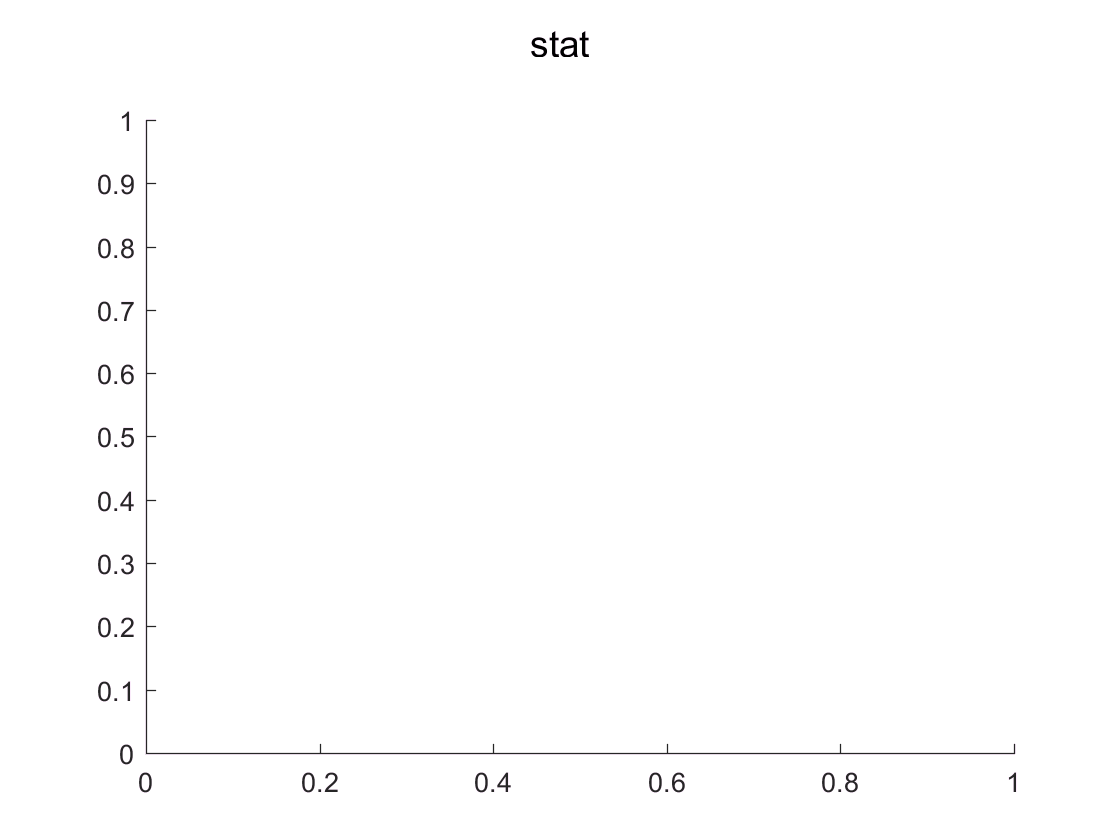

nthStimDetailsStruct = groupStimDetails{n};
nthTrialCond = groupTrialCond{1,n};
nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n};

% CONTRAST calc's
clear con
clear conOrderedByTrial  
clear conOrderedByTrialMeetCriteria 
clear uniqueContrasts
clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end
conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later

%  DURATION Calc's
clear dur
clear durOrderedByTrial  
clear durOrderedByTrialMeetCriteria 
clear uniqueDurations
% extract duration field from stimDetails
clear durs
for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end
durOrderedByTrial = dur(nthTrialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueDurations = unique(dur);

% CON & DUR TOGETHER
clear conAndDur 
clear conAndDurOrderedByTrial 
clear conAndDurOrderedByTrialMeetCriteria
conAndDur = [con; dur];
conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);




clear d  
for d = durat
    
    % clear this before contrasts & points loop
    clear allPtsAllCon
    
    loopCounter = 1;
    
    clear c
    for c = 1:length(uniqueContrasts)
    %for c = cont
    
        clear i
        %for i = visArea
        for i = 1:length(RoundXpts)

            clear n 
            for n = 1:nGroup % for each session/mouse
                
                % EXTRACT VARS from GROUP CELL ARRAYS
                nthStimDetailsStruct = groupStimDetails{n};
                nthTrialCond = groupTrialCond{1,n};
                nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n}; 
               
                % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
        
                % CONTRAST calc's
                clear con
                clear conOrderedByTrial  
                clear conOrderedByTrialMeetCriteria 
                clear uniqueContrasts
                clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
                for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
                    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
                end
                conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
                conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueContrasts = unique(con); % for looping over contrast values later
                
                %  DURATION Calc's
                clear dur
                clear durOrderedByTrial  
                clear durOrderedByTrialMeetCriteria 
                clear uniqueDurations
                % extract duration field from stimDetails
                clear durs
                for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
                    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
                end
                durOrderedByTrial = dur(nthTrialCond); 
                durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueDurations = unique(dur);
        
                % CON & DUR TOGETHER
                clear conAndDur 
                clear conAndDurOrderedByTrial 
                clear conAndDurOrderedByTrialMeetCriteria
                conAndDur = [con; dur];
                conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
                conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                
                % in preparation for making pixel wise figures of fluroescene at different stim conditions,
                % make figure legends
                [reigons,cons4Legend,cons4axes,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
                % durs4Legend = {'16 ms','33 ms', '66 ms', '133 ms', '266 ms'}
                durs4Legend = {'100 ms'};
        
                % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
                nthPTSdfof = groupPTSdfof{1,n};
                nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
                nthBaselineIdx = groupBaselineIdx{1,n};
                
                % EXTRACT RUN vs STAT TRIAL INDICIES
                nthIdxRunTrials = groupIdxRunTrials{1,n};
                nthIdxStatTrials = groupIdxStatTrials{1,n}; 
        
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,nthIdxStatTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthSTATtrials = length(idxCthDthSTATtrials);

                % part directly from old script
                
                clear recomboOnePtAllFramesAllTrialMinusMeanBase
                clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase

                % collect all cth dth trials over all frames for the ith point nth session
                clear onePtAllFramesAndTrials % new var each point
                onePtAllFramesAndTrials = squeeze(nthPTSdfof(i,:,idxCthDthSTATtrials)); 
                onePtAllFramesAndTrials = onePtAllFramesAndTrials';

                % for every trial in nth session cth dthstims, 
                % subtract the baseline value at that point from each frame value
                clear tr % for each trial in onePtAllFramesAndTrial
                for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames

                    % getting TRIAL VECTOR
                    clear onePtAllFramesOneTrial % make new var for each trial
                    % index into each trace/vector & save as variable
                    onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);

                    % getting MEAN BASEline VALUE for each TRIAL
                    clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                    % collect 4 baseline frames for tr-th ith trial
                    allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,nthBaselineIdx);

                    clear mean4baseFramesOnePtOneTrial
                    % get mean value of baseline values for ith point
                    mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                    mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);

                    % BASEline CORRECTion of TRIAL VECTOR
                    % new baseline-corrected trace for each trial
                    onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;

                    % collect CORRECTed TRIAL VECTORS in matrix
                    % (only clear this outside the loop for each point - want to collect over sessions)
                    % this is for 1 session only? no...
                    recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;

                    hold on % hold for next trial
                
                end % end tr loop, move on to plot each trial not N=1th session
      
                hold on % hold for plotting mean over subplot
                
            end % end n loop - now have all trials for all sesstions at cth contrast 
        
            % still in i loop, which is w/in c loop
            
            % get mean baselined trace across all trials, for *all* sessions, *one* contrast, *one point*
            statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
            % collect mean df vs frames at *one* contrast for *every* visual area
            allPtsOneCon(:,:,i) = statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase; % should give 1 x frames x pts
            
%             % plot one contrast at a time, then move to next visual area on same plot
%             x_axis = 1:length(statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase);
%             subplot(2,4,c)
%             plot(x_axis,statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%             title(uniqueContrasts(c))
% 
%             ylim(yLimit)
%             xlim([1 length(x_axis)])

            %ax = gca;
            %x.XTick = [1:1:length(x_axis)];

            %loopCounter = loopCounter + 1;
       
            % go to next visual area & plot same contrast
            
        % collect df/f vs frames at all contrasts, for each point    
        %allPtsAllCon(:,:,i) = allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
            
        end % end i loop, move to next contrast
        
        % at next contrast, 1 x # frames mean trace will be created for all points again (1 x 18 x5)
        % stack these for each contrast
        
        % this creates 7 (contrasts) x 18 (frames) x 5 (pts)
        allPtsAllConsSTAT(c,:,:) = allPtsOneCon;
        
        %legend(reigons)
           
    end % end c loop

end % end d loop


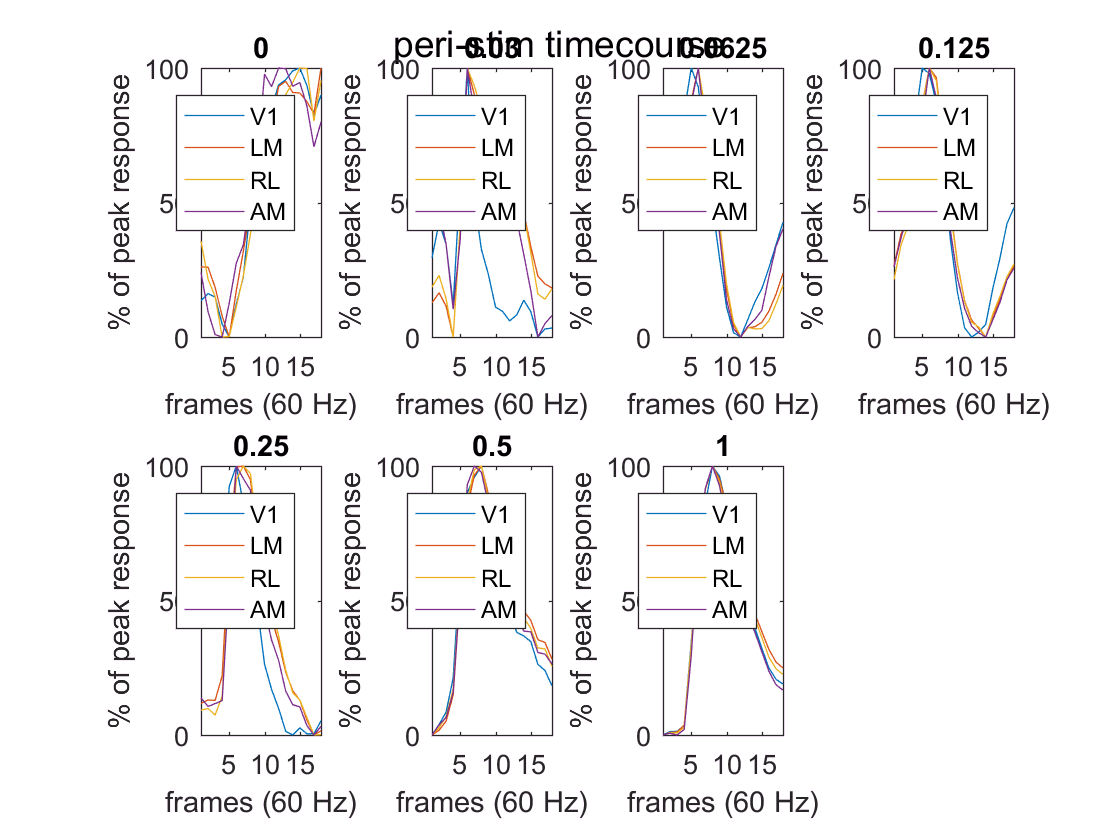

% do again but differently

figure
suptitle('peri-stim timecourse')

clear peakLatency

clear c
for c = 1:length(uniqueContrasts)
    
    clear i
    for i = 1:length(RoundXpts)-1 % no need to include control here
        
        % get each trace for each point at cth contrast
        ithCthMnTraceSTAT = allPtsAllConsSTAT(c,:,i);
        
        % make so that entire range of df/f values are positive (no negatives)
        ithCthMnTraceSTAT = ithCthMnTraceSTAT-min(ithCthMnTraceSTAT);
        
        % get the peak response
        maxIthCthMnTraceSTAT = max(ithCthMnTraceSTAT);
        
        % store peak latency of each contrast for each point
        % gives # pts x contrasts vector
        peakLatency = find(ithCthMnTraceSTAT == maxIthCthMnTraceSTAT);
        
        peakLatencyAllConsAllPts(i,c) = peakLatency;
        
        % ratio
        ithCthMnTraceSTATratio = ithCthMnTraceSTAT/maxIthCthMnTraceSTAT;
        % percent
        ithCthMnTraceSTATpercentOfMax = ithCthMnTraceSTATratio*100;
        
        % on each subplot plot all ith mean traces for the cth contrast
        subplot(2,4,c)
        x_axis = 1:length(ithCthMnTraceSTATpercentOfMax);
        plot(x_axis,ithCthMnTraceSTATpercentOfMax)
        
        ylim([0 100])
        xlim([1 length(x_axis)])
        
        ax = gca;
        x.XTick = [1:1:length(x_axis)];
         
        title(uniqueContrasts(c)) 
        
        ylabel('% of peak response')
        xlabel('frames (60 Hz)')
        
        hold on
        
    end
    
    legend(reigons)
    
end 

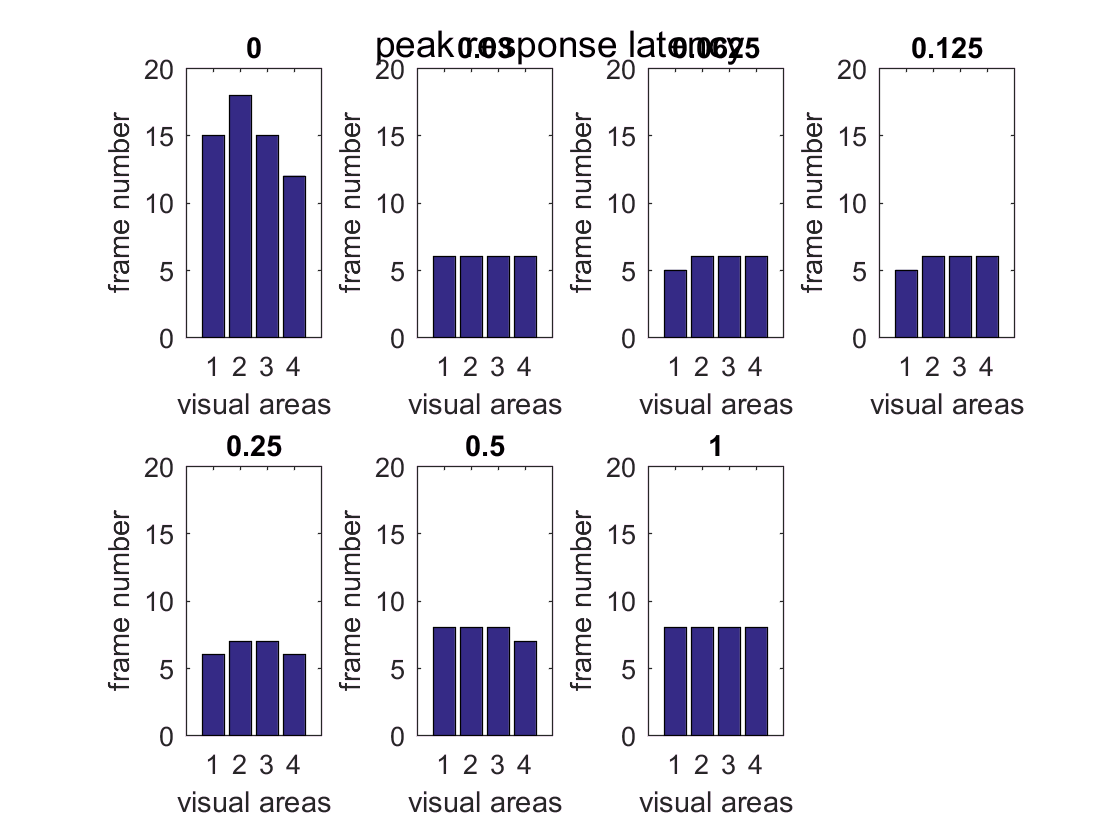

% plot latency for each area/contrast

figure
suptitle('peak response latency')

clear c
for c = 1:length(uniqueContrasts)
    
    %clear i
    %for i = 1:length(RoundXpts)-1 % no need to include control here
        
        % extract contrsat latency response curve for one point & one contrast at a time
        
        %remember peakLatencyAllConsAllPts is pts x contrast
        
        clear latencyOnePtAllCons % make new for each point
        latencyAllPtOneCon = peakLatencyAllConsAllPts(:,c); % take one row of contrasts
        %latencyOnePtCthCons = latencyOnePtAllCons(c);
        
        subplot(2,4,c)
        
        x_axis = 1:length(uniqueContrasts);
        bar(latencyAllPtOneCon)
        
        ylim([0 20])
        %ylim([3 20])
        
        %y.YTick = [1:1:20];
        
        %set(gca, 'YDir','reverse')
        
        ylabel('frame number')
        xlabel('visual areas')
        
        title(uniqueContrasts(c))
        
%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%         set(gca,'xtick',1:7); 
%         set(gca,'xticklabel',xt);
        
       % hold on % plot all c latencies for the next point
        
    %end % end pts loop - move onto next pt 
    
    %legend(reigons)
    %legend({'a1','a2','a3','a4'})
    
end % end c loop